# **Nueral Networks and Learning Machines**

**Instructor: Dr. Farrokhi  |  Student: Erfan Riazati  |  Spring 2024**

format short;
close all;
clear;
clc;

### Double-Moon Structure Dataset

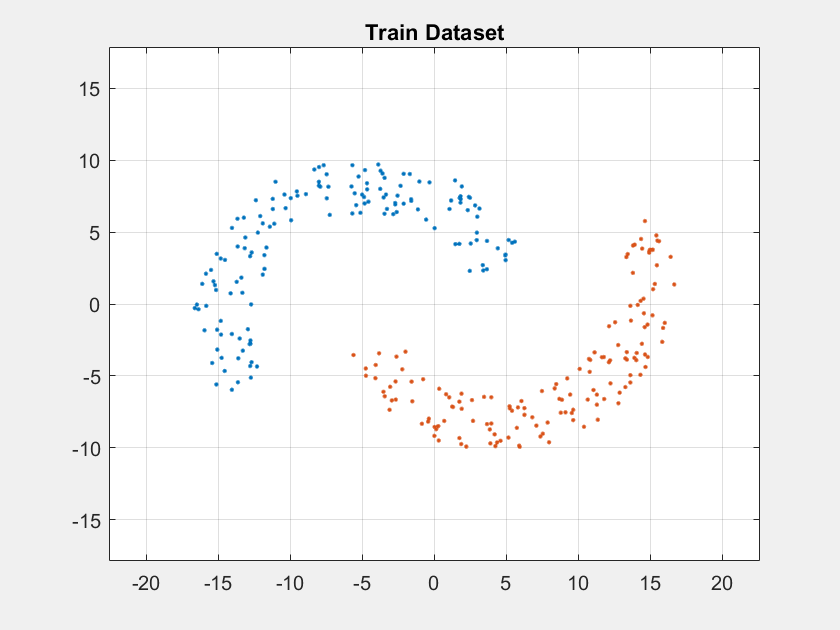

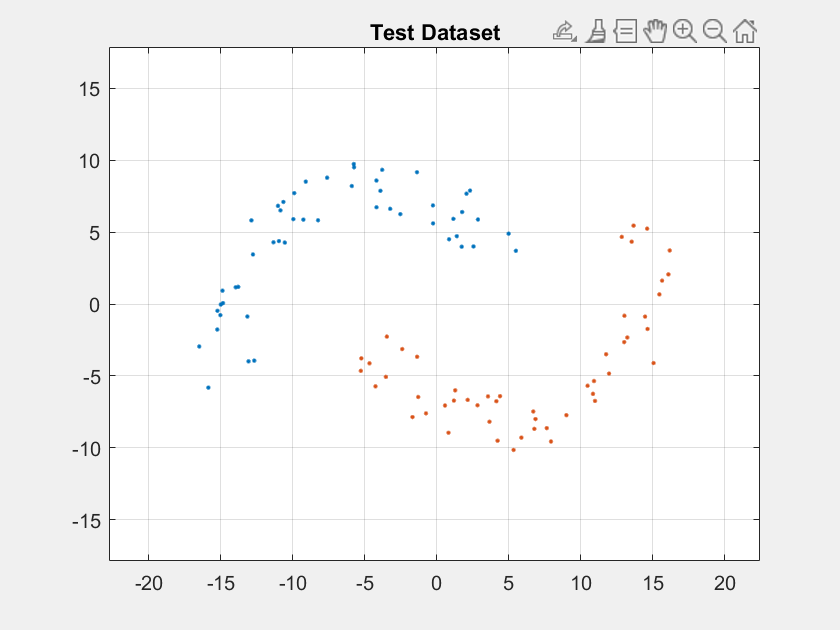

radius = 10; width = 4; theta = 25; distance = 1;
N = 400; train2total = 0.75; drawPatterns = true;

[train, test] = doubleMoonStructure( radius, width, theta, distance, ...
                                     N, train2total, drawPatterns );

### Rosenblatt's Perceptron

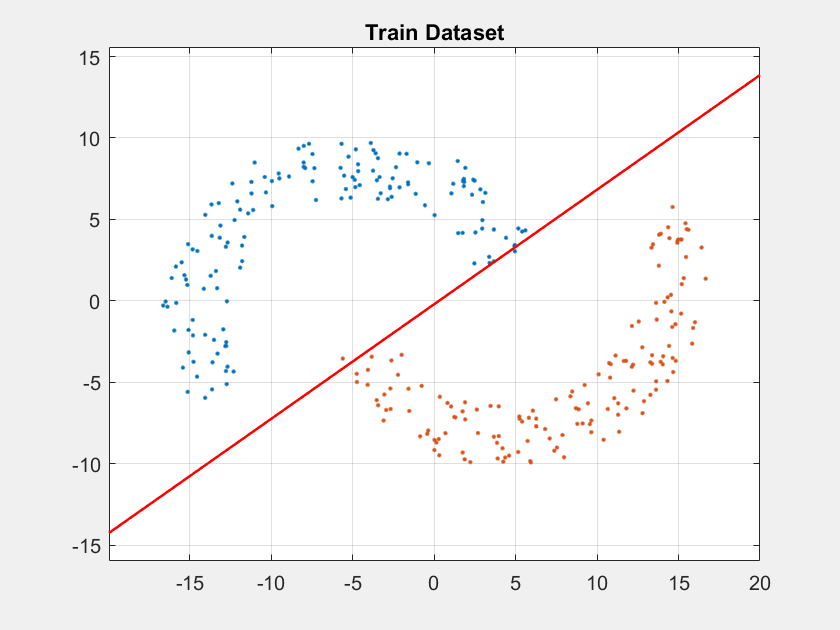

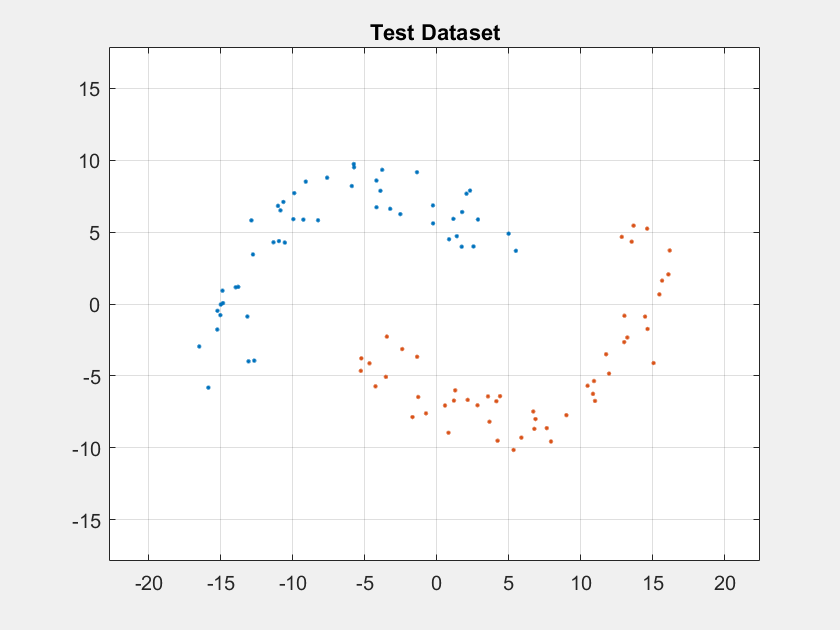

eta = 1;            % Learning-Rate Parameter
w0 = [ 0, 0, 0 ];   % Initialize the Weights

% Training the Perceptron
weights = trainPerceptron(train, eta, w0, true);

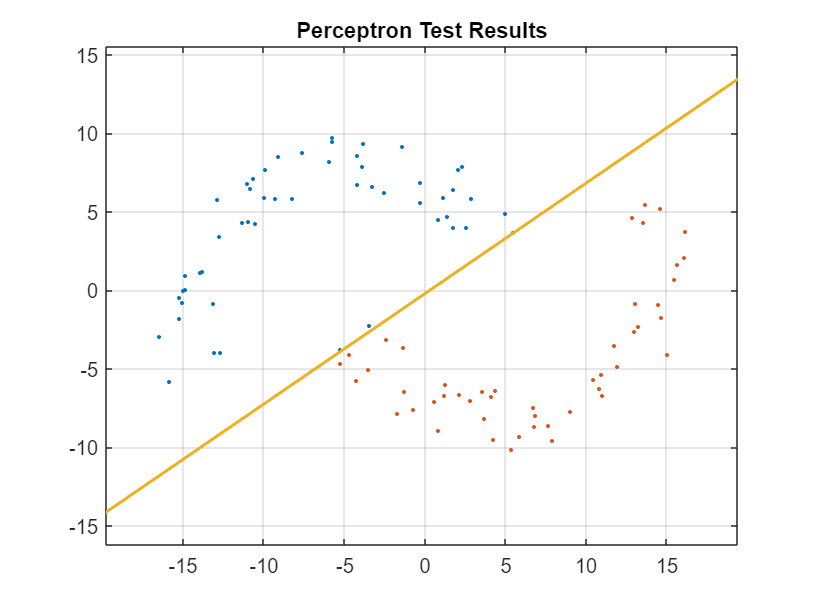

% Verification on the Test Dataset
% Concluding the Accuracy of the Decision Boundry
[class1, class2, accuracy] = testPerceptron(test, weights);


disp("Perceptron Accuracy (%)");

Perceptron Accuracy (%)


disp(accuracy);

    98


### Multi-Layer Perceptron

% phi(v) = a*tanh(bv)   a = 1.7159, b = 2/3

m0 = 2;
m1 = 20;
m2 = 1;

epsilon = 0.01;

weights = normrnd(0, epsilon^2, [2, 20]);
bias = normrnd(0, epsilon^2, [1, 2]);

e_k = zeros([1, 100])

e_k =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


d_k = train(:, 3)

d_k =      1
     1
     1
     1
     1
     1
     1
     1
     1
     1


function [activation] = phi(v)
    % phi_j(v_j(n)) = a.tanh(b.v_j(n))
    a = 1.7159;
    b = 2/3;
    activation = a*tanh(b*v);
end

function [derivative] = phi_derivative(y)
    % phi_j'(v_j(n)) = (b/a)[a - y][a + y]
    a = 1.7159;
    b = 2/3;
    derivative = (b/a)*(a - y)*(a + y);
end